## Ex 1

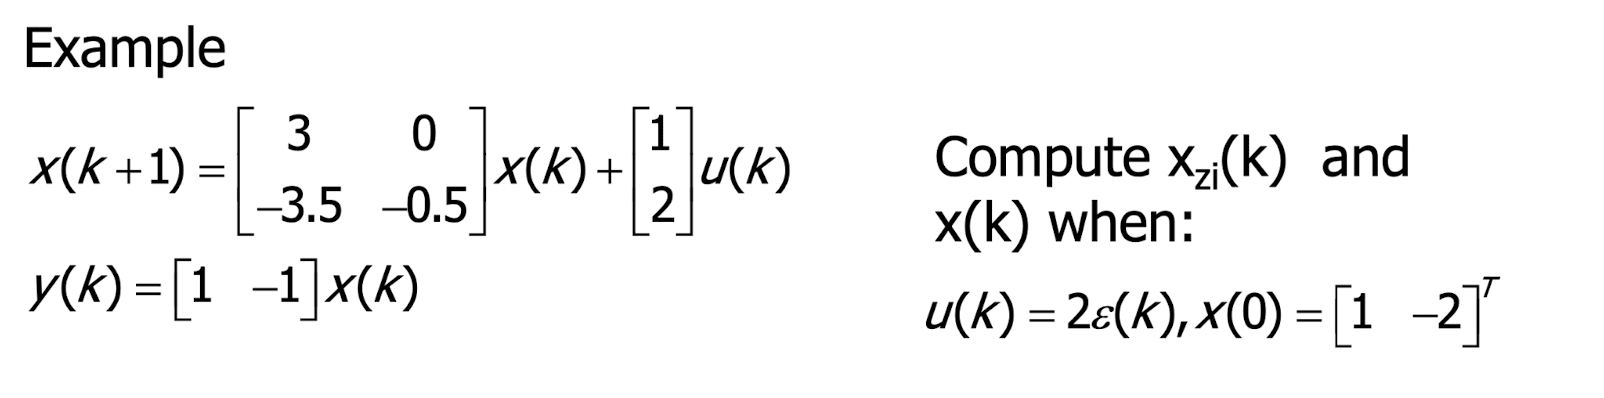

A = [3 0; -3.5 -0.5];
B = [1;2];
C = [1 -1];
x0 = [1;-2];

z = tf('z',1);
U = 2*z/(z-1);

Xzi = minreal(zpk(z*inv(z*eye(2)-A)*x0), 1e-2)


Xzi =
 
  From input to output...
         z
   1:  -----
       (z-3)
 
       -2 z (z-1.25)
   2:  -------------
       (z-3) (z+0.5)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.


Xzs = minreal(zpk(inv(z*eye(2)-A)*B*U),1e-2)


Xzs =
 
  From input to output...
           2 z
   1:  -----------
       (z-3) (z-1)
 
          4 z (z-4.75)
   2:  -------------------
       (z-3) (z-1) (z+0.5)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.


% continua...

## Ex 2

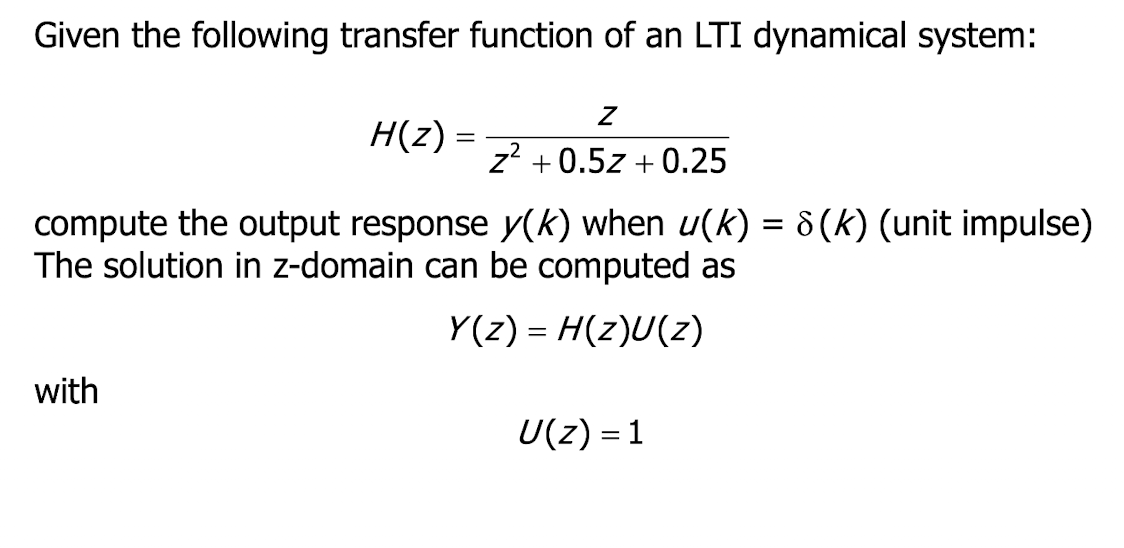

clear
z = tf('z',1);
H = z/(z^2+0.5*z+0.25);
U = 1;
Y = H*U; % non metto minreal tanto U è 1
[nY,dY] = tfdata(Y,'v');
[rY,pY,kY] = residuez(nY,dY)

rY =    0.0000 - 1.1547i
   0.0000 + 1.1547i


pY =   -0.2500 + 0.4330i
  -0.2500 - 0.4330i


kY = 0

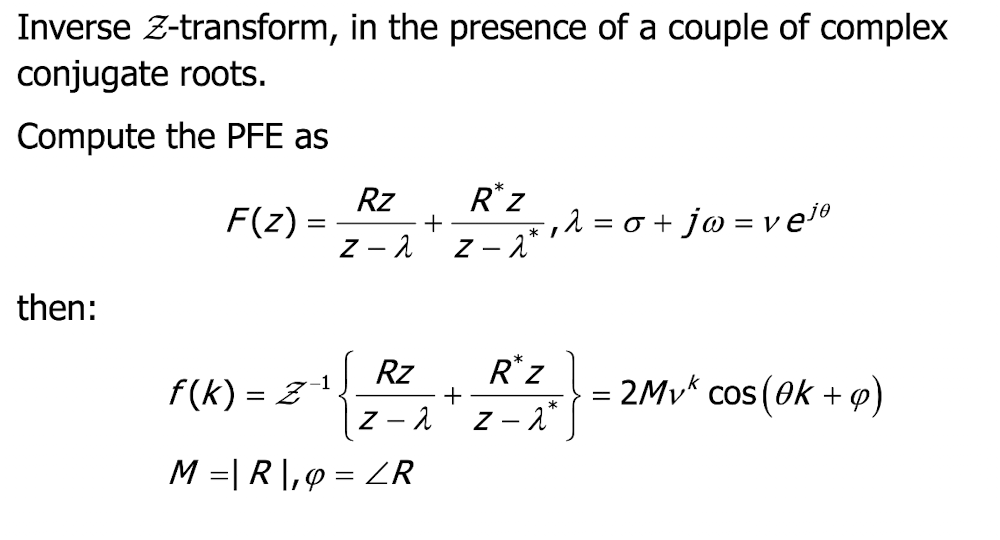

M = abs(rY(1)); M_2 = 2*M

M_2 = 2.3094

phi = angle(rY(1))

phi = -1.5708

theta = angle(pY(1))

theta = -2.0944

nu = abs(pY(1))

nu = 0.5000

REGOLE:

Ricordarsi la formula non ci piace, però si osservi che:

- bisogna calcolare modulo e fase sia di R che di lambda

- modulo e fase di lambda (i.e. del polo) sono legati a k (si vedano nu e theta), invece modulo e fase di R (i.e. del residuo) sono "più indipendenti"

Regola non scritta: usare il primo dei due poli complessi coniugati (se usiamo il secondo il modulo non cambia, mentre l'angolo si) (regola da verificare)

## Ex 3

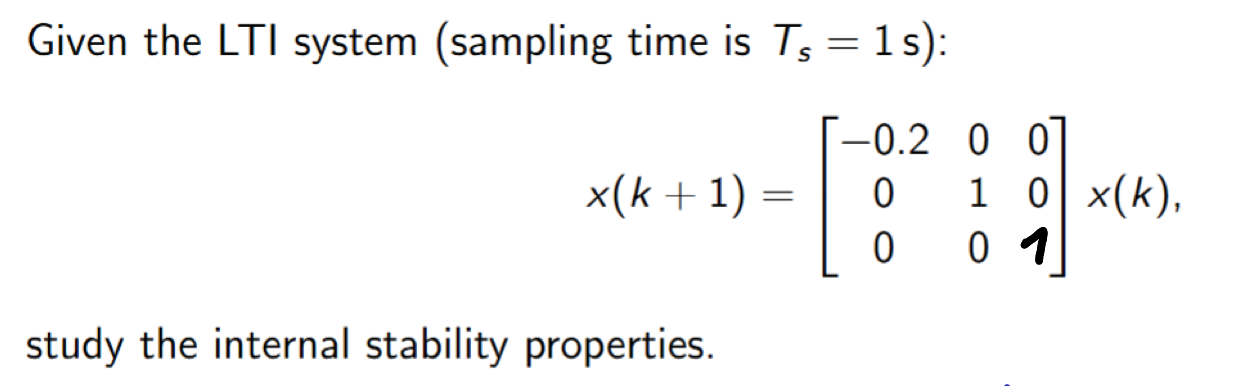

clear
A = [-0.2 0 0; 0 1 0; 0 0 1];
eig(A)

ans =    -0.2000
    1.0000
    1.0000


% doppio eig in 1 => devo calcolare min mult pol

roots(minpoly(A))

ans =     1.0000
   -0.2000


% il polinomio minimo ha solo una radice in 1 => STABILE
